# **Envelope Based "Snap" Detection**

## **References **

**Codes based on: **

Bohnenstiehl DR, Lillis A, Eggleston DB (2016) The Curious Acoustic Behavior of Estuarine Snapping Shrimp: Temporal Patterns of Snapping Shrimp Sound in Sub-Tidal Oyster Reef Habitat. PLoS ONE 11(1): e0143691. https://doi.org/10.1371/journal.pone.0143691

**Waveform data used in this example from: **

Ricci SW, Eggleston DB, Bohnenstiehl DR, Lillis A (2016) Temporal soundscape patterns and processes in an estuarine reserve. Mar Ecol Prog Ser 550:25-38. [https://doi.org/10.3354/meps11724 ](https://doi.org/10.3354/meps11724)

## **Generate a kernel  **

First you need to look at your data in the time domain and really zoom in to identify the peak time of a snap that you want to consider as a potential template.   

Below, the variable **st** (snap time) represents the index (points into the file) of one of these peaks. 

You can build a template off of a single snap envelope that is representative, or stack multiple envelopes together and base the template off of the stack.  In either case, test multiple kernals to make sure the detections aren't overly sensitive to the exact kernel you are using. 

This example makes a kernel using a single snap. 

Once you've identified a start index (st), we need to load and filter the file that contain that snap 

FILE_TAKEN='67670026.140624070002.wav';  % gets save with kernel file 
[y,kfs]=audioread(FILE_TAKEN);           % read the wavefrom 
gain=185.4; cal_low=10^(gain/20);        % gain for ST300 (in this example)  
y=y*cal_low; y=y-mean(y);                % apply calibration and subtract mean 
flt_low=4000;  flt_high=20000; 
temp=bandpass_del(y,flt_low, flt_high,kfs,5);   % bandpass 7000-20000 Hz, modify as needed 


Then we want to extract the snap 

st=2415292;                 % index represents the approximate peak of a snap you want to use as a template 
wav=temp(st-20:st+200+20);  % extract a segment around the snap
                            % the numbers here are points, so if you have a
                            % different sample, you may need to pull
                            % different numbers of points.
                            

env=abs(hilbert(wav));      % calculate the envelope 
env=env(11:end-21); wav=wav(11:end-21);  % trim the ends and center so that the peak of 
                                         % the envelope at 50 points - adjust as needed 
                                         % Note that if you have data with a different 
                                         % sample rate you'd want to adjust
                                         % this.  50 points = 0.5208 msec @
                                         % 96,000 kHz sample rate 
                                     
fprintf('Number of points is %1.0f in the kernel', numel(env) )

Number of points is 210 in the kernel

fprintf('Number of sec is %1.10f in the kernel',  numel(env)*(1/kfs)) 

Number of sec is 0.0021875000 in the kernel

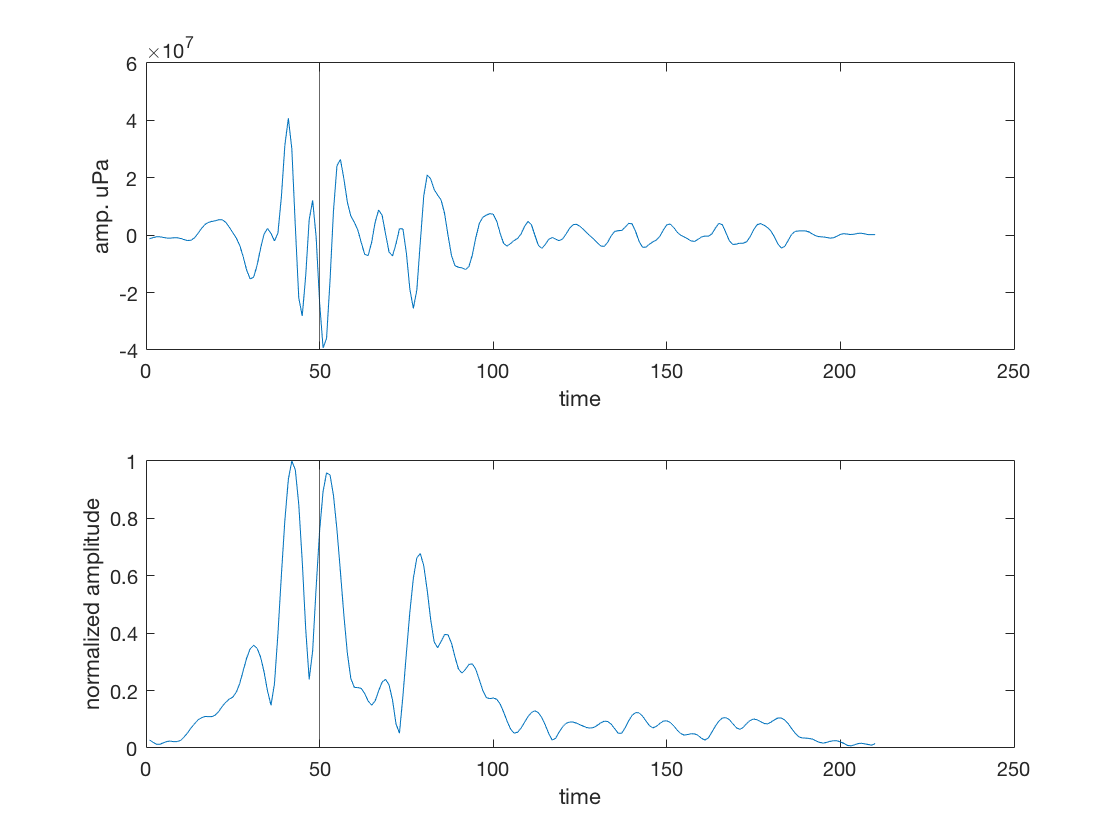

env=env./max(env); % normalize the amplitude of the envelope 
figure; subplot(2,1,1); plot(wav); xlabel('time'); ylabel('amp. uPa'); xline(50);
subplot(2,1,2); plot(env); xlabel('time'); ylabel('normalized amplitude');xline(50); % plot the waveform and the envelope 

Now we want to smooth the kernel to make it more general, while preserving it's over all shape.     

We've generally done this by fitting high oder polynomials to the segment leading up to the peak and another decaying from the peak. 

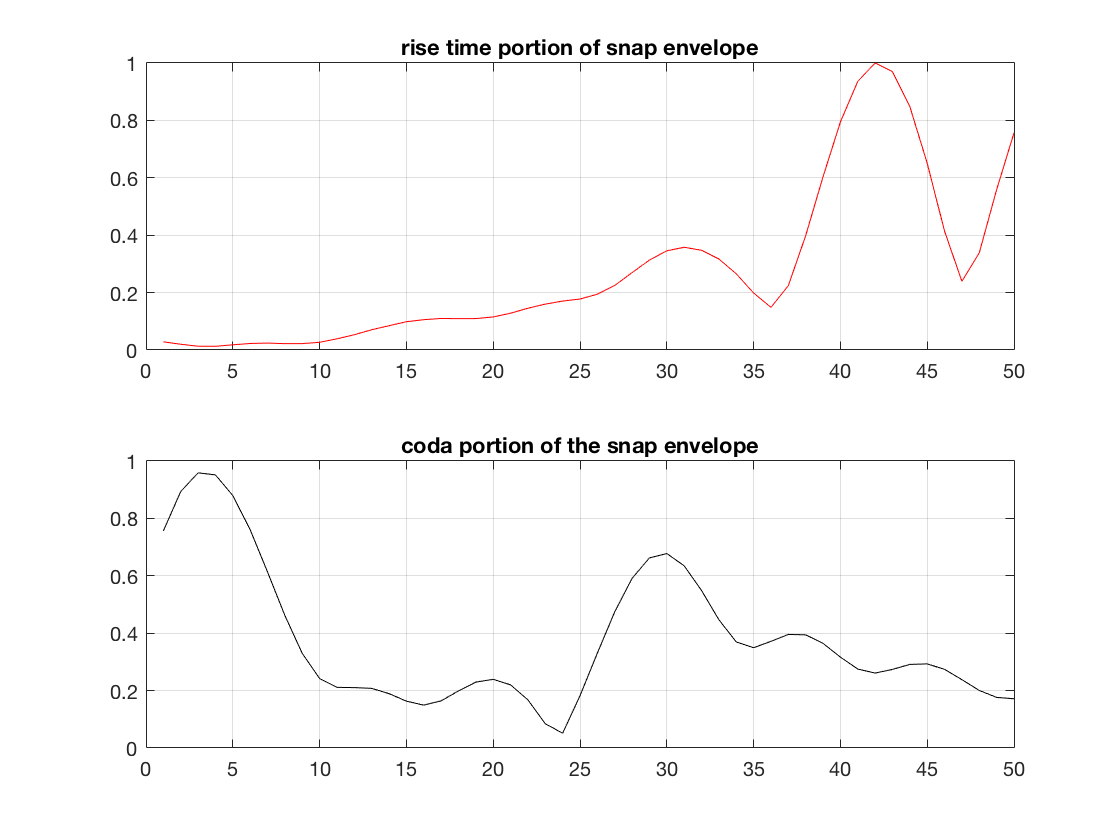

figure; subplot(2,1,1); plot(env(1:50),'b'); hold on; 
subplot(2,1,2); plot(env(50:99),'r');
w = warning ('off','all');  % will suprise badly conditioned warnings for the polynomials 
f1=polyfit([1:50]',env(1:50), 7); %7th order polynomial 
f2=polyfit([1:50]',env(50:99), 7);

seg1 = polyval(f1,1:1:50); seg1=seg1-seg1(1); seg2 = polyval(f2,1:1:50)-seg1(1);

subplot(2,1,1); plot(env(1:50),'-r'); title('rise time portion of snap envelope'); grid on 
subplot(2,1,2); plot(env(50:99),'-k'); title('coda portion of the snap envelope'); grid on; 

Now put the smoothed segments together and pad the start with zeroes 

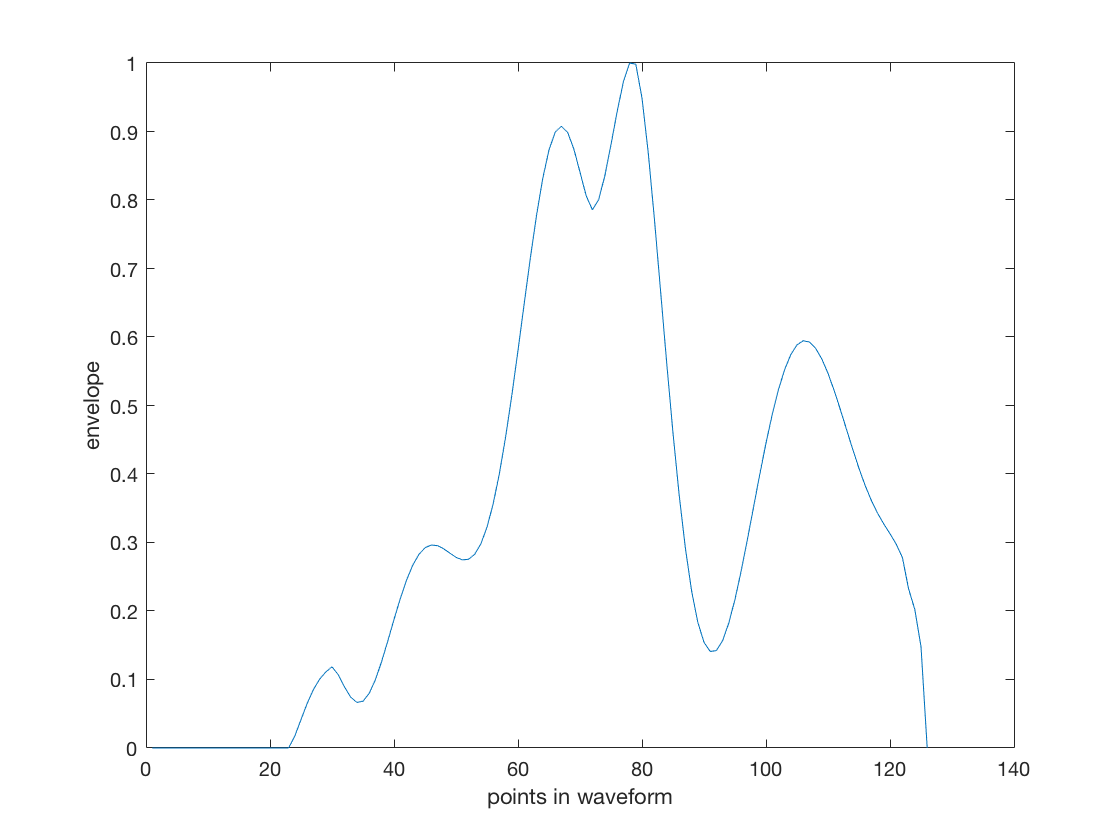

kern=cat(2,zeros(1,25),seg1,seg2,0); kern(kern < 0)=0;  % pad the front wiht 25 zeros (25/96000 sec). 
kern=smooth(kern,7); kern=kern/max(kern);   % smooth and re-normalize 
klen=length(kern);figure; plot(kern);  xlabel('points in waveform'); ylabel('envelope')

kern=kern'; 
pk=75;  % kernel peak after all that adjustment is at 75 points in  
save kern_example.mat kern klen pk wav env kfs flt_low flt_high FILE_TAKEN 

## Deploy the Kernel 

For testing purposes, let's deploy the kernel on a portion of this same waveform; 

clear
FILE_TAKEN='67670026.140624070002.wav';  % gets save with kernel file 
[y,fs]=audioread(FILE_TAKEN);           % read the wavefrom 
y=y(1:floor(end/3));                      % take 1/3 of the file for testing (~40 sec) 
gain=185.4; cal_low=10^(gain/20);        % gain for ST300 (in this example)  
y=y*cal_low; y=y-mean(y);                % apply calibration and subtract mean 

min_det_score = 0.75;  % no harm in setting this low and then you can filter later
[det_sam, det_tim, det_amp, det_score, ncc, nlg,file_dbrms] = snap_detect_func(y,'kern_example.mat',min_det_score,fs,1); 

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


Now we can filter the data a bit more by removing quiet snaps with **amplitudes < amp_thres** and those with **det_scores <  score_thres**

amp_thres=10.^(115/20);  % set at the 90% quantile level for all waveform recordings 
                         % when filtered in the flt_low flt_high                   
score_thres=0.8; 

% going to make new variable with only those passing
a=find(det_amp < amp_thres & det_score <= score_thres);  
det_amp2=det_amp; det_amp2(a)=[]; 
det_sam2=det_sam;  det_sam2(a)=[];  
det_tim2=det_tim;  det_tim2(a)=[]; 
det_score2=det_score; det_score2(a)=[];


Now lets plot the detection score vs. time 

figure; 
  ax(1)=subplot(3,1,1); hold on; grid on; 
  h1=plot(ax(1), nlg*1/fs, ncc);  
  h2=plot(ax(1),[0,max(nlg)*1/fs],[0.75,0.75]); 
  plot(ax(1),det_tim, det_score,'or');
  plot(ax(1),det_tim2, det_score2,'ok');
  ylabel('detection score') 
  
  set(get(get(h1,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off'); % Exclude line from legend
  set(get(get(h2,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off'); % Exclude line from legend
 legend({'failed threshold','accepted threshold'},'Location','southeast');

Plot the detections on the waveform 

    flt_low=4000; flt_high=20000; 
    pfilt=bandpass_del(y,flt_low,flt_high,fs,5); % will be used later for plotting
    t=(0:1:length(pfilt)-1)*1/fs;  % time axis 
    

  ax(2)=subplot(3,1,2);hold on; grid on; 
  h3=plot(ax(2),t,pfilt);   
  h4=plot(ax(2),[0,max(t)],[amp_thres,amp_thres],'--k');
  h5=plot(ax(2),[0,max(t)],-1*[amp_thres, amp_thres],'--k');
  
 plot(ax(2),det_tim, det_amp,'.r','MarkerSize',10);
 plot(ax(2),det_tim2, det_amp2,'.k','MarkerSize',10);
 ylabel('amplitude uPa') 
  
set(get(get(h3,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off'); % Exclude line from legend  
set(get(get(h4,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off'); % Exclude line from legend
set(get(get(h5,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off'); % Exclude line from legend
legend({'failed threshold','accepted threshold'},'Location','southeast')
 

Plot the spectrogram 

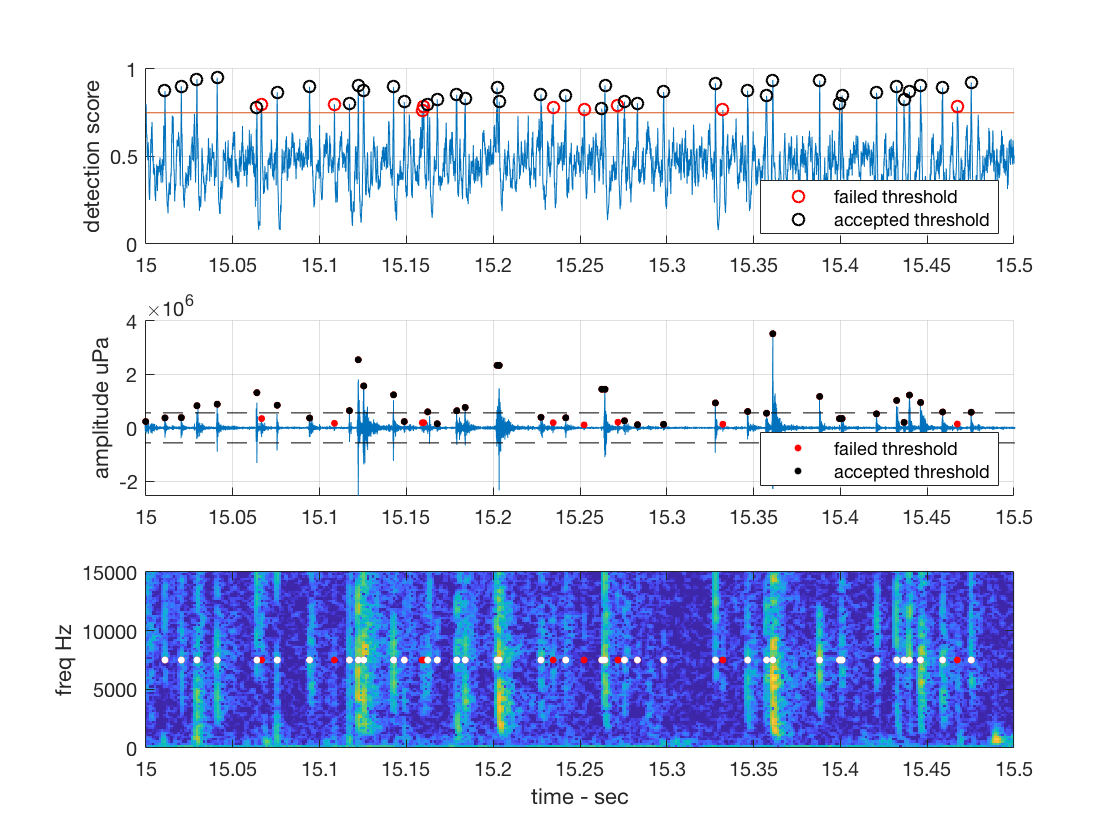

win=2^9; 
[~,F,T,Pxx]=spectrogram(y,win,floor(win*0.75),[],fs); 
ax(3)= subplot(3,1,3); 
imagesc(ax(3),T,F,10*log10(Pxx)); hold on; 
plot(ax(3),det_tim,7500*ones(1,numel(det_score)),'.r','MarkerSize',10); 
plot(ax(3),det_tim2,7500*ones(1,numel(det_score2)),'.w','MarkerSize',10);
ylim([0,15000]);  axis xy;  caxis([40,90]); xlabel('time - sec'); ylabel('freq Hz') 
linkaxes([ax(3) ax(2) ax(1)],'x'); 
xlim([15,15.5]);

Above:   You can zoom in and check out the performance 

## How to Implement 

To implement this in practice, make a kernel and save it, then loop through each data file you have and save the variables related to the detections. 

help snap_detect_func

   
  [det_sam, det_tim, det_amp, det_score, ncc, nlg,file_dbrms]...
              = snap_detect_func(y,kern_mat_file,min_det_score,fs,use_par)
  
    Where the INPUTS are:
    y = pressure corrected waveform (unfiltered)
        {Note that the sample rate is given in kernel file}  
  
   'kern_mat_file' = text string the contains name of the mat file 
     Variable in the file are: 
      kern = eveloped kernel function 
      klen = length of kernel (# samples)
      pk =  position of peak in kernel (# samples) 
      kfs = sample rate of kernel and data 
      flt_low & flt_high - bandpass used to make kernel 
    
    min_det_score is the minimum correlation coefficent needed to declare a
    detection.  Set this low (e.g., 0.7) and then you can filter detections
    later. 
  
    fs = sample rate of the data 
  
    use_par = 1 will run this function using MATLAB's parallel processing
    pool 
  
    OUTPUTS are: 
    det_sam - detection position in points 
    

If you are using data with a sample rate other than 96,000, then within the snap_detect_func, you may need to adjust the 'MINPEAKDISTANCE' option in the findpeaks line and length of the left zero pad added to the kernel. 